clear
clc

# Euler Angles

Euler angles are used to describe the orientation of a rigid body with respect to a observation reference frame

- Considering an orthogonal right-handed axis system

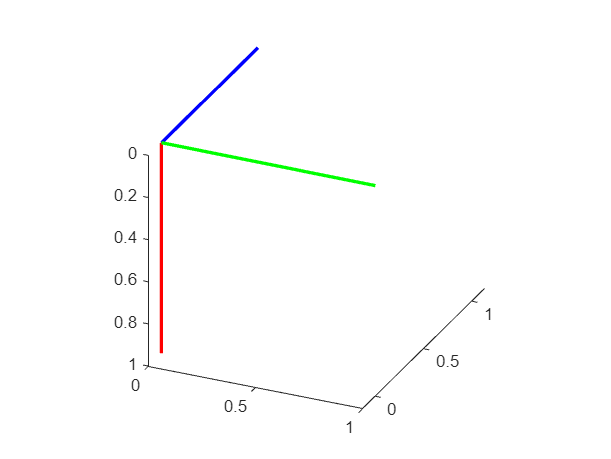

% Define a set of unit vectors
x = [0, 1; 0, 0; 0, 0];
y = [0, 0; 0, 1; 0, 0];
z = [0, 0; 0, 0; 0, 1];

figure(1)
clf
hold on 
axis equal

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'linewidth', 2, 'color', 'blue')
plot3(y(1,:), y(2,:), y(3,:),'linewidth', 2, 'color', 'green')
plot3(z(1,:), z(2,:), z(3,:),'linewidth', 2, 'color', 'red')

view([-65.690 26.325])

## Yaw

- Rotation occurs about the z-axis, meaning $z_1 =z_0$

- Rotation occurs clockwise about the axis of rotation, meaning the x vector rotates towards the right

Yaw: $\left\lbrack \begin{array}{c}
x_1 \\
y_1 \\
z_1 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\psi \;\right) & -\sin \left(\psi \;\right) & 0\\
\sin \left(\psi \;\right) & \cos \left(\psi \;\right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 
\end{array}\right\rbrack$

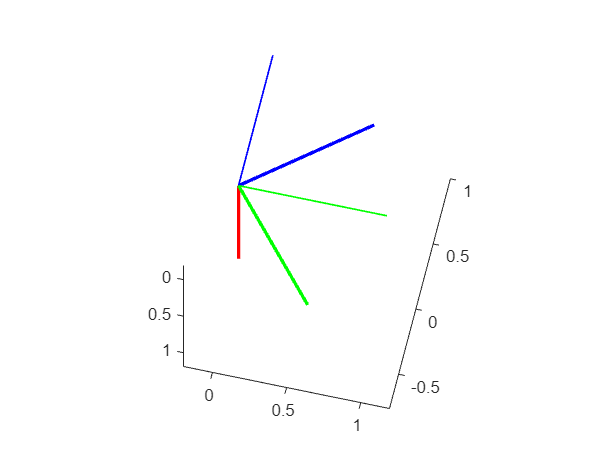

psi =50;
yaw = [cosd(psi), -sind(psi), 0; sind(psi), cosd(psi), 0; 0, 0, 1];

x1 = yaw * x;
y1 = yaw * y;
z1 = yaw * z;


figure(2)
clf
hold on 
axis equal

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'linewidth', 1, 'color', 'blue')
plot3(y(1,:), y(2,:), y(3,:),'linewidth', 1, 'color', 'green')
plot3(z(1,:), z(2,:), z(3,:),'linewidth', 1, 'color', 'red')

plot3(x1(1,:), x1(2,:), x1(3,:),'linewidth', 2, 'color', 'blue')
plot3(y1(1,:), y1(2,:), y1(3,:),'linewidth', 2, 'color', 'green')
plot3(z1(1,:), z1(2,:), z1(3,:),'linewidth', 2, 'color', 'red')

view([-76.98 61.35])

## Pitch

- Rotation occurs about the y-axis, meaning $y_1 =y_0$

- Positive pitch results in clockwise rotation about the y-axis, meaning the x-vector goes upwards

Pitch $\left\lbrack \begin{array}{c}
x_2 \\
y_2 \\
z_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\theta \;\right) & 0 & \sin \left(\theta \;\right)\\
0 & 1 & 0\\
-\sin \left(\theta \;\right) & 0 & \cos \left(\theta \;\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
y_1 \\
z_1 
\end{array}\right\rbrack$

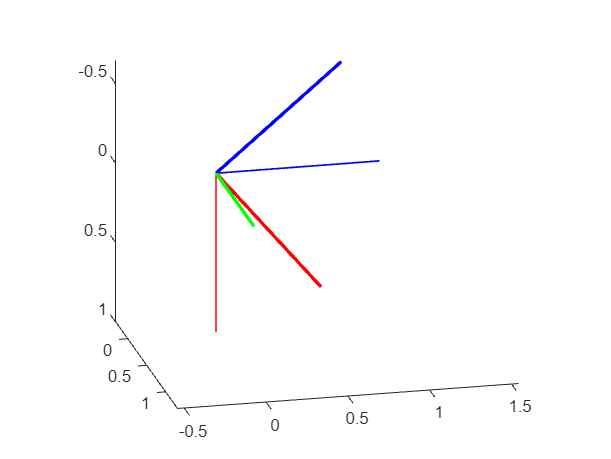

theta =40;
pitch = [cosd(theta), 0, sind(theta); 0, 1, 0; -sind(theta), 0, cosd(theta)];

x1 = pitch * x;
y1 = pitch * y;
z1 = pitch * z;

figure(3)
clf
hold on 
axis equal

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'linewidth', 1, 'color', 'blue')
plot3(y(1,:), y(2,:), y(3,:),'linewidth', 1, 'color', 'green')
plot3(z(1,:), z(2,:), z(3,:),'linewidth', 1, 'color', 'red')

plot3(x1(1,:), x1(2,:), x1(3,:),'linewidth', 2, 'color', 'blue')
plot3(y1(1,:), y1(2,:), y1(3,:),'linewidth', 2, 'color', 'green')
plot3(z1(1,:), z1(2,:), z1(3,:),'linewidth', 2, 'color', 'red')

view([-13.084 18.955])

## Roll

- Rotation  occurs about the y-axis, meaning $x_1 =x_0$

- Positive roll results in clockwise rotation about the x-axis, meaning the y-vector goes to the right (or down)

Roll:  $\left\lbrack \begin{array}{c}
x_3 \\
y_3 \\
z_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(\phi \;\right) & -\sin \left(\phi \right)\\
0 & \sin \left(\phi \right) & \cos \left(\phi \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_2 \\
y_2 \\
z_2 
\end{array}\right\rbrack$

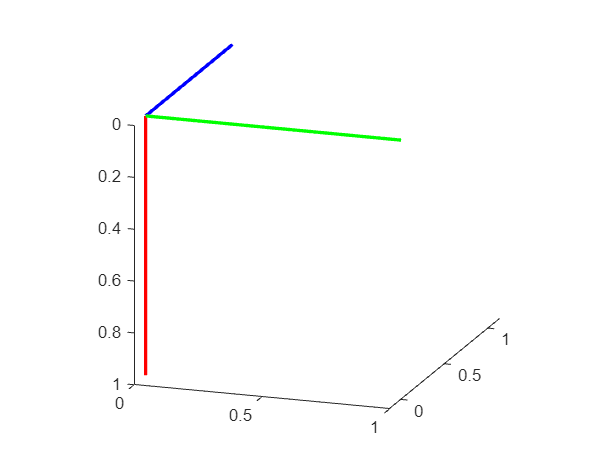

phi = 0;
roll = [1, 0, 0; 0, cosd(phi), -sind(phi); 0, sind(phi), cosd(phi)];

x1 = roll * x;
y1 = roll * y;
z1 = roll * z;

figure(4)
clf
hold on 
axis equal

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'linewidth', 1, 'color', 'blue')
plot3(y(1,:), y(2,:), y(3,:),'linewidth', 1, 'color', 'green')
plot3(z(1,:), z(2,:), z(3,:),'linewidth', 1, 'color', 'red')

plot3(x1(1,:), x1(2,:), x1(3,:),'linewidth', 2, 'color', 'blue')
plot3(y1(1,:), y1(2,:), y1(3,:),'linewidth', 2, 'color', 'green')
plot3(z1(1,:), z1(2,:), z1(3,:),'linewidth', 2, 'color', 'red')

view([-71.24 16.20])

## Compiled Rotation

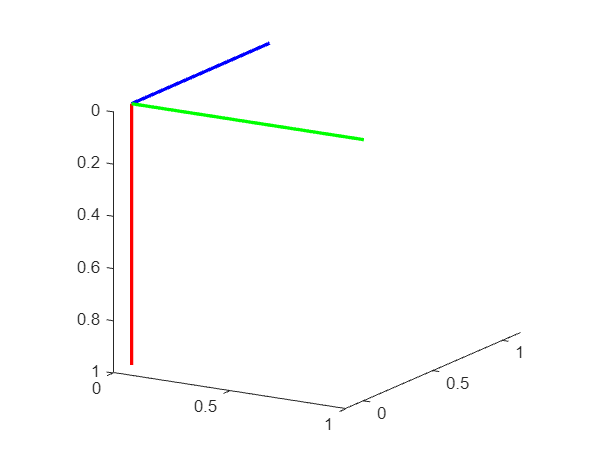

phi = 180; 
theta = 180;
psi = 180;

yaw = [cosd(psi), -sind(psi), 0; sind(psi), cosd(psi), 0; 0, 0, 1];
pitch = [cosd(theta), 0, sind(theta); 0, 1, 0; -sind(theta), 0, cosd(theta)];
roll = [1, 0, 0; 0, cosd(phi), -sind(phi); 0, sind(phi), cosd(phi)];

cosine_matrix = yaw * pitch * roll;

x1 = cosine_matrix * x;
y1 = cosine_matrix * y;
z1 = cosine_matrix * z;


figure(5)
clf
hold on 
axis equal

set(gca,'ydir', 'reverse')
set(gca,'zdir', 'reverse')

plot3(x(1,:), x(2,:), x(3,:),'linewidth', 1, 'color', 'blue')
plot3(y(1,:), y(2,:), y(3,:),'linewidth', 1, 'color', 'green')
plot3(z(1,:), z(2,:), z(3,:),'linewidth', 1, 'color', 'red')

plot3(x1(1,:), x1(2,:), x1(3,:),'linewidth', 2, 'color', 'blue')
plot3(y1(1,:), y1(2,:), y1(3,:),'linewidth', 2, 'color', 'green')
plot3(z1(1,:), z1(2,:), z1(3,:),'linewidth', 2, 'color', 'red')

view([-71.24 16.20])